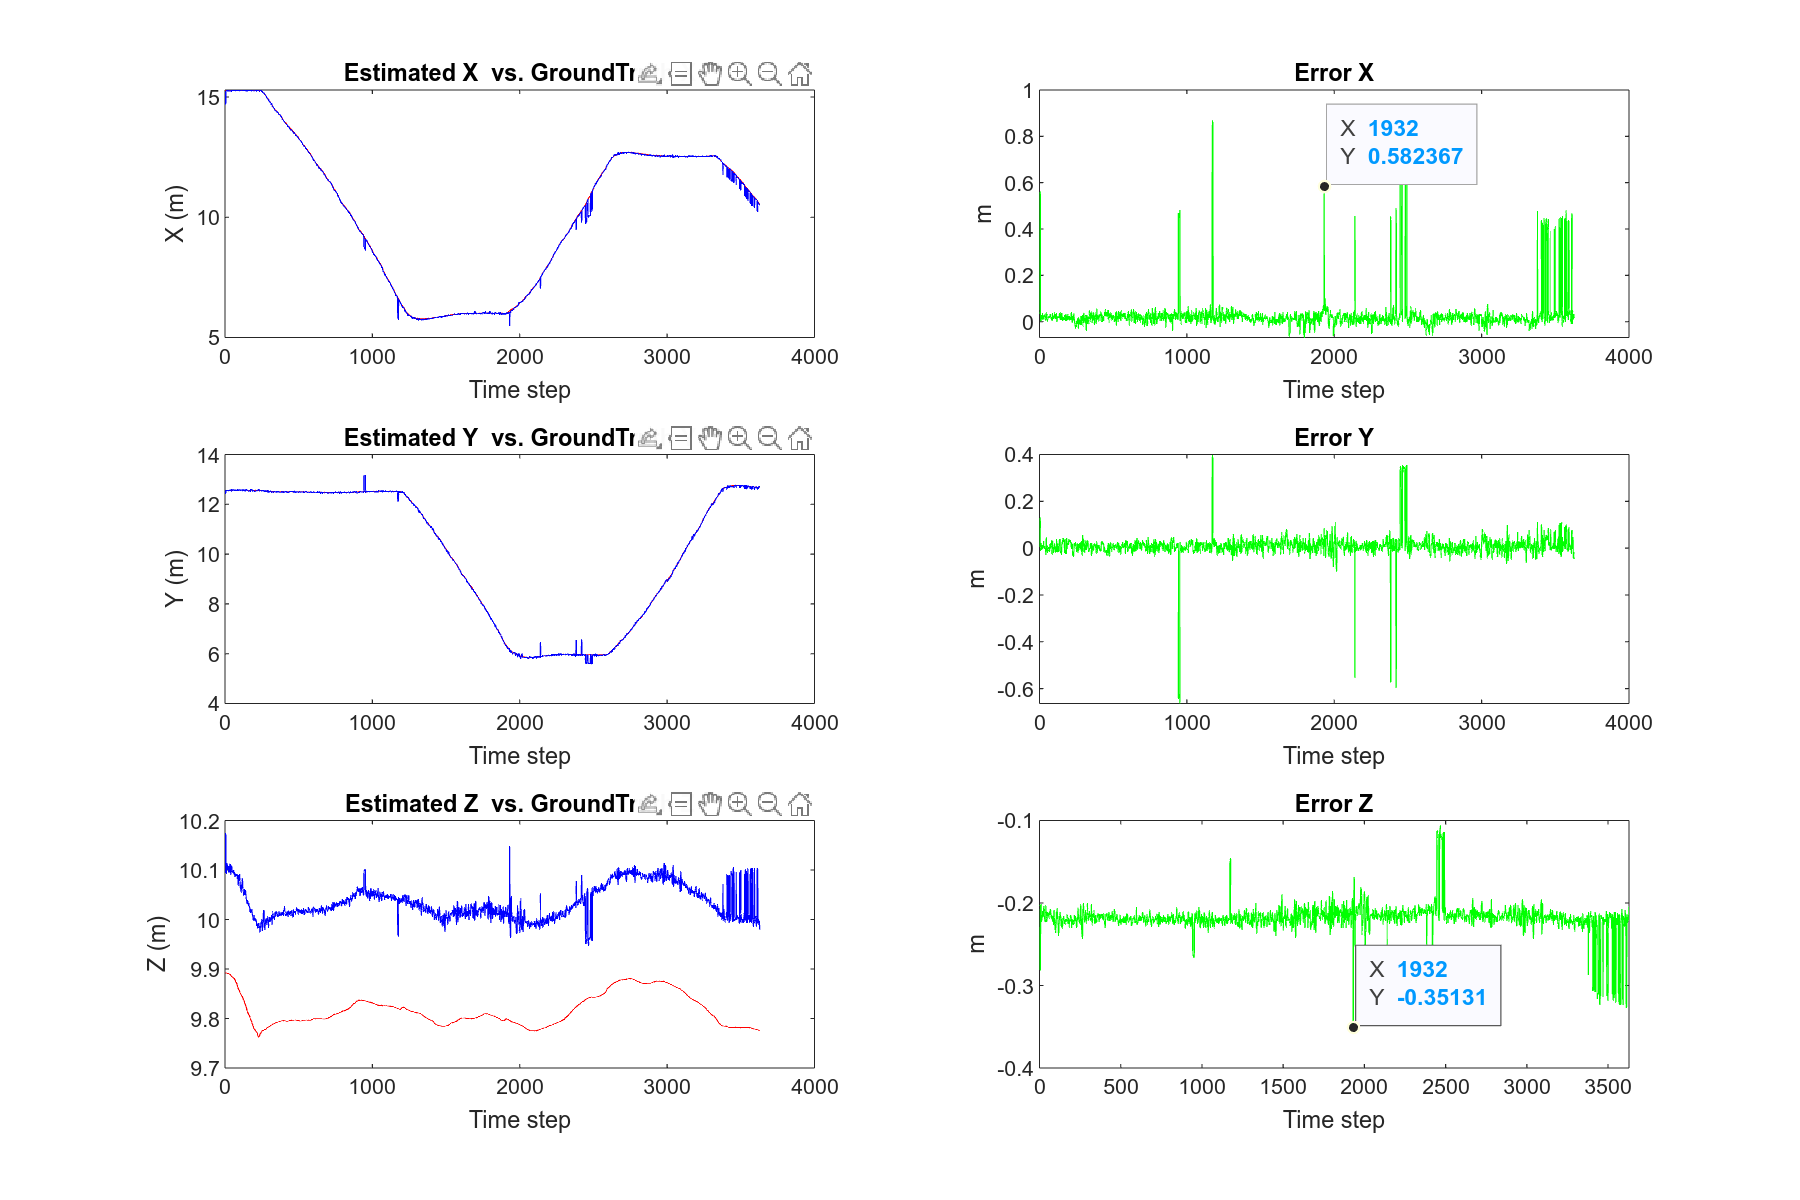

clear;clc;close;

% Data
filename_1 = "/home/leo/mts/src/coverage/record/uav2.csv";
M = readmatrix(filename_1);

% Variable
counter = size(M);

groundTruth = M(:,13:15);
estimation = M(:,16:18);

begin = 2;
end_ = counter(1);

ErrorX = groundTruth(begin:end_,1) - estimation(begin:end_,1);
ErrorY = groundTruth(begin:end_,2) - estimation(begin:end_,2);
ErrorZ = groundTruth(begin:end_,3) - estimation(begin:end_,3);

RMSX = sqrt(sum(ErrorX(:,1).^2)/(counter(1)-1));
RMSY = sqrt(sum(ErrorY(:,1).^2)/(counter(1)-1));
RMSZ = sqrt(sum(ErrorZ(:,1).^2)/(counter(1)-1));

hold on;

t = tiledlayout(3, 2, 'TileSpacing','loose');

% X - axis
nexttile;

plot(begin:1:end_, groundTruth(begin:end_,1), "r", begin:1:end_, estimation(begin:end_,1), "b");
title('Estimated X  vs. GroundTruth X');
xlabel("Time step"); ylabel("X (m)");

hold on;

% X - Error
nexttile;

plot(begin:1:end_, groundTruth(begin:end_,1) - estimation(begin:end_,1), "g");
title('Error X');
xlabel("Time step"); ylabel("m");

hold on;

% Y - axis
nexttile;

plot(begin:1:end_, groundTruth(begin:end_,2), "r", begin:1:end_, estimation(begin:end_,2), "b");
title('Estimated Y  vs. GroundTruth Y');
xlabel("Time step"); ylabel("Y (m)");

hold on;

% Y - Error
nexttile;

plot(begin:1:end_, groundTruth(begin:end_,2) - estimation(begin:end_,2), "g");
title('Error Y');
xlabel("Time step"); ylabel("m");

hold on;

% Z - axis
nexttile;

plot(begin:1:end_, groundTruth(begin:end_,3), "r", begin:1:end_, estimation(begin:end_,3), "b");
title('Estimated Z  vs. GroundTruth Z');
xlabel("Time step"); ylabel("Z (m)");

hold on;

% Z - Error
nexttile;

plot(begin:1:end_, groundTruth(begin:end_,3) - estimation(begin:end_,3), "g");
title('Error Z');
xlabel("Time step"); ylabel("m");

hold on;

% Configuration of Figure
xlim([0 end_]);

set(gcf,'units','points','position',[0,0,1080,720]);